# Определение нот композиции по суммам

clear all
close all

path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

Tab_F_1 = [65.41  69.3  73.42  77.78  82.41  87.31  92.5  98  103.83  110  116.54  123.47];
k = 2.^(0:7) / 2;
Tab_F = k' .* repmat(Tab_F_1, 8, 1);

M = zeros(8, 12);
Ms = M;
NOTES = 88;
NFFT = 1024;
N_zero = Fs - NFFT;     % Кол-во нулей после вырезки. Я буде для частотного шага 1Гц
N = floor(2/(NFFT/Fs)); % Количество вырезок за 2 секунды
ds = 2;                 % В сколько раз уменьшить спектр. Минимум 2 - нормально


notes_lin = zeros(1, N*NOTES);
k_interp = Fs/NFFT - 1;
zeros_num = floor( k_interp*NFFT );
Zer = zeros(zeros_num, 1);
L2 = ( (k_interp+1)*NFFT);
Indexes = floor(L2 * Tab_F / Fs + 1);   % NOT FLAT!!!

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
data = reshape(z,4*Fs,[]);  % Каждая нота отдельно
data = data(1:(N*NFFT),:);
Y = zeros(N, NOTES);
for i = 1:NOTES
    Y(:,i) = i;
end
Y = reshape(Y, 1, [])';
z = reshape(data, 1, [])';
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


v1 = [1 1 1 1 1 1 1 1] * 1/8;
v2 = [0 1 0 1 0 1 0 1] * 1/3;
v3 = [0 0 1 0 0 1 0 0] * 1/2;
v4 = [0 0 0 1 0 0 1 0] * 1/2;
v5 = [0 0 0 0 1 0 0 0]; 
v6 = [0 0 0 0 0 1 0 0];
v7 = [0 0 0 0 0 0 1 0];
v8 = [0 0 0 0 0 0 0 1];
V = [v1; v2; v3; v4; v5; v6; v7; v8];

Очистка

clear path y Tab_F_1 k v1 v2 v3 v4 v5 v6 v7 v8

Находим ноты

p_error = 0;

for i = 1:(N*NOTES-1)
    
    n1 = i*NFFT;         % Задаю пределы для вырезания участка сигнала
    n2 = (i+1)*NFFT - 1;
    
    S = z(n1: n2);              % Берем участок сигнала
    S2 = vertcat (Zer, S);      % Интерполируем спектр
    Spec = abs(fft(S2));        % Находим спектр сигнала
    M = Spec(Indexes);          % Заполняем матрицу нот
    
    Ms = V * M;
    
    [Val, Ind] = max(Ms',[],[1 2], 'linear');   % Нахожу индекс максимума
    
    notes_lin(i) = Ind;         % Сохраняю текущую ноту
    
    if Ind ~= Y(i)
        p_error = p_error + 1;
    end
    
    if mod(i,2000) == 0
        figure(i)
        mesh(Ms);
        xlabel("Notes")
        ylabel("Octaves")
        title("Matrix number #" + string(i) + ". LinIndex = " + string(Ind))
    end
    
end

plot(notes_lin)
hold on
plot(Y)
ylabel("Линейный индекс ноты")
title("Определение нот во времени по суммам")

p_error = 100 * p_error / (N*NOTES)

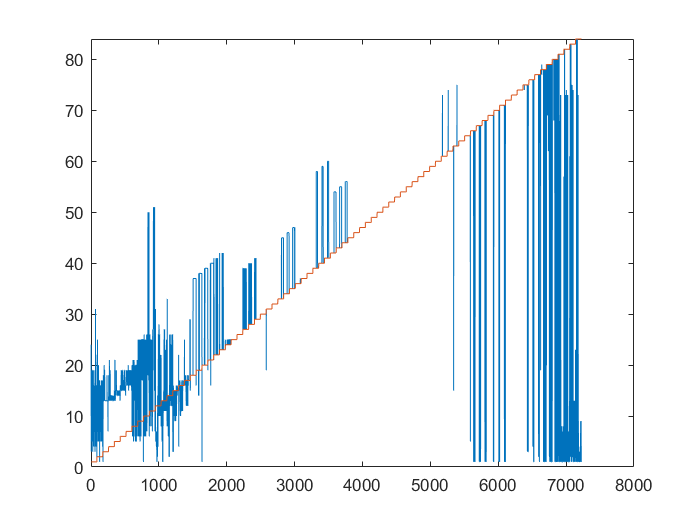

clear all
close all

path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

Tab_F_1 = [65.41  69.3  73.42  77.78  82.41  87.31  92.5  98  103.83  110  116.54  123.47];
k = 2.^(0:6) / 2;
Tab_F = k' .* repmat(Tab_F_1, 7, 1);

M = zeros(7, 12);
Ms = M;
v1 = [1 1 1 1 1 1 1 ] * 1/7;
v2 = [0 1 1 1 1 1 1 ] * 1/6;
v3 = [0 0 1 1 1 1 1 ] * 1/5;
v4 = [0 0 0 1 1 1 1 ] * 1/4;
v5 = [0 0 0 0 1 1 1 ] * 1/3; 
v6 = [0 0 0 0 0 1 1 ] * 1/2;
v7 = [0 0 0 0 0 0 1 ];
V = [v1; v2; v3; v4; v5; v6; v7];
clear path y Tab_F_1 k v1 v2 v3 v4 v5 v6 v7

NOTES = 84;
NFFT = 1024;
N_zero = Fs - NFFT;     % Кол-во нулей после вырезки. Я буде для частотного шага 1Гц
N = floor(2/(NFFT/Fs)); % Количество вырезок за 2 секунды

data = reshape(z,4*Fs,[]);  % Каждая нота отдельно
data = data(1:(N*NFFT),:);
data = data(:, 1:87);      % Откидываем 5тую октаву ноту До
data = data(:,4:end);      % Откидываю первые 3 ноты суб-контр октавы
Y = zeros(N, NOTES);
for i = 1:NOTES
    Y(:,i) = i;    
end
Y = reshape(Y, 1, [])';


k_interp = Fs/NFFT - 1;
zeros_num = floor( k_interp*NFFT );
Zer = zeros(zeros_num, 1);
L2 = ( (k_interp+1)*NFFT);
Indexes = floor(L2 * Tab_F / Fs + 1);   % NOT FLAT!!!

p_error = 0;
notes_lin = zeros(1, N*NOTES);
for i = 1:NOTES
    
    for j = 1:N
        
        n1 = (j-1)*NFFT + 1;         
        n2 = (j)*NFFT; 
        S = data(n1:n2, i);
        S2 = vertcat(Zer, S);
        Spec = abs(fft(S2));        % Находим спектр сигнала
        M = Spec(Indexes);          % Заполняем матрицу нот
        Ms = V * M;
        
        ar_ind = N*(i-1) + j;
        [~, Ind] = max(Ms',[],[1 2], 'linear');   
        notes_lin(ar_ind) = Ind;         
        
        if Ind ~= Y(ar_ind)
            p_error = p_error + 1;
        end  
        
%         if mod(j,50) == 0
% %             figure
% %             mesh(Ms);
% %             xlabel("Notes")
% %             ylabel("Octaves")
% %             title("Real note " + string(Y(N*(i-1) + j)) + ". Result = " + string(Ind))
%             
%             figure
%             plot(Spec(1:3000))
%             title("Real note " + string(Indexes(Y(N*(i-1) + j))) + "Hz. Result = " + string(Indexes(Ind)) + "Hz")
%         end
          
    end

end

plot(notes_lin)
hold on
plot(Y)
%ylabel("Линейный индекс ноты")
%title("Определение нот во времени по суммам")
ylim([0, 84])


p_error = 100 * p_error / (N*NOTES)

p_error = 31.9491

D = data(:, 1:87);      % Откидываем 5тую октаву ноту До
D = D(:,4:end);         % Откидываю первые 3 ноты суб-контр октавы
D;                      % 84 ноты, контр-октава -- четвертая

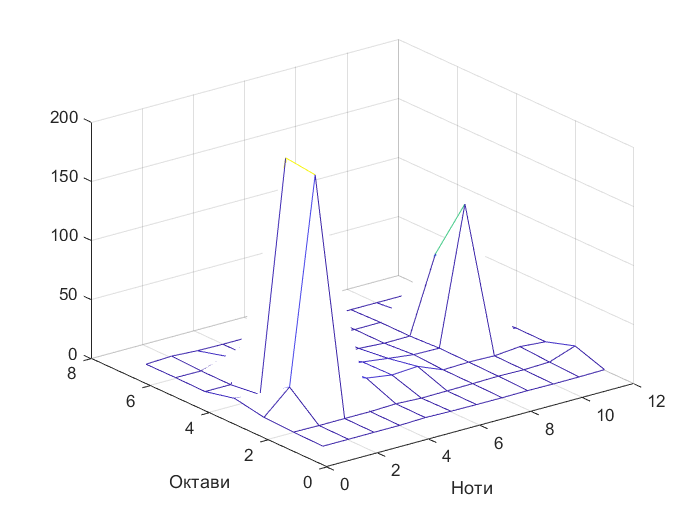

i = 15;
a = data(:, i);
Sp = abs(fft(a));
M = Sp(Indexes); 
Ms = V * M;

figure
mesh(M);
xlabel('Ноти')
ylabel('Октави')

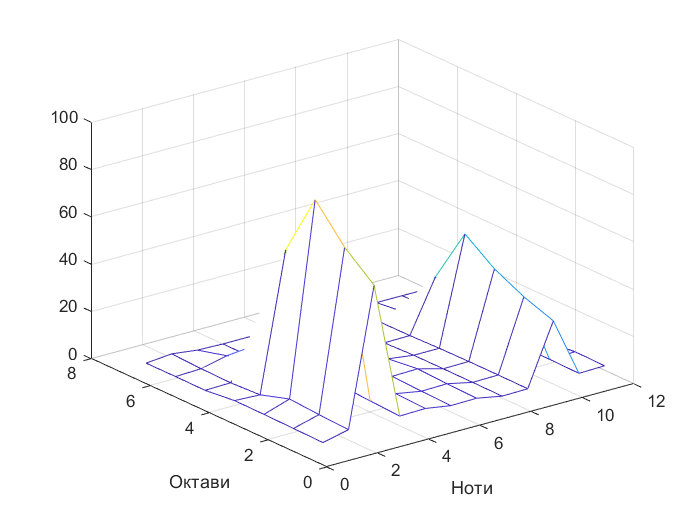


figure
mesh(Ms)
xlabel('Ноти')
ylabel('Октави')